% Demo program na rozpoznanie 6 koznych ochoreni na zaklade 34 parametrov
% z vysetreni lekarov
% Cielom je natrenovat NS, aby dokazala taketo ochorenia rozpoznavat

% Načítame dataset zo súboru
filename = 'dermatology_data.txt';
M = csvread(filename); 

% Oddelíme vektor výstupov
t = M(:,35);
target = zeros(size(t, 1), 6);      % vystupne data pre NS
% Vytvoríme maticu žiadaných hodnôt
for i=1:size(t,1)
    target(i, t(i)) = 1;
end
targets=target'

targets =      0     1     0     1     0     0     0     0     0     0     1     0     0     1     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     1     1
     1     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     1     0     0     1     0     1     0     0     1     0     0     1     0     0     0     0     1     0     0     0     0     0
     0     0     1     0     1     0     0     1     0     0     0     0     0     0     1     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     1     1     0     0     0     0   


% Matica vstupnych trénovacích dát
inputs = M(:,1:34)'

inputs =      2     3     2     2     2     2     2     2     2     2     3     2     3     2     2     1     2     3     2     1     2     3     2     2     2     2     1     1     3     1     3     3     2     2     2     3     1     1     3     2     0     2     2     2     1     2     3     1     2     3
     2     3     1     2     3     3     1     2     2     2     3     2     3     3     2     1     2     3     1     1     1     2     2     2     0     1     1     2     2     1     2     2     3     1     1     3     1     1     2     1     1     1     1     1     2     0     1     1     2     1
     0     3     2     2     2     2     0     3     1     1     2     0     1     3     3     0     1     3     3     0     1     2     0     2     0     1     0     2     2     2     1     0     3     1     2     2     1     1     1     1     0     1     1     1     1     1     1     1     1     1
     3     2     3     0     2     0     2     3     0     0     1     3     2     0    


% Vytvoríme neurónovú sieť s jednou skrytou vrstvou
% Počet skrytých neurónov vo vrstve
hiddenLayerSize = 25;

% Neurónová sieť určená na klasifikáciu dát
net = patternnet(hiddenLayerSize);

net.divideFcn = 'dividerand';  % Rozdelíme dáta náhodne

% Nastavíme pomery pre rozdelenie datasetu
net.divideParam.trainRatio = 70/100; 
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 30/100;

% Nastavenie parametrov
net.trainParam.goal = 0.0001; % Sum-squared error goal.
net.trainParam.show = 20;           % Frequency of progress displays (in epochs).
net.trainParam.epochs = 500;       % Maximum number of epochs to train.
net.trainParam.min_grad = 1e-10;  % ukoncovacia podmienka na min. gradient 

% chybova funkcia
net.performFcn

ans = 'crossentropy'

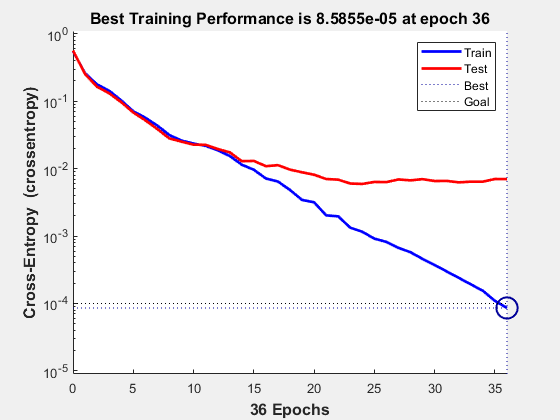


%% Natrénujeme neurónovú sieť
[net,tr] = train(net,inputs,targets);

% Zobrazenie chyby trenovania
figure, plotperform(tr)


% Otestujeme sieť
outputs = net(inputs);
errors = gsubtract(targets,outputs);
performance = perform(net,targets,outputs)

performance = 0.0022


% Vypočíta hodnotu chybovej funkcie pre Trénovacie, Validačné and 
% Testovacie dáta
trainTargets = targets .* tr.trainMask{1};
valTargets = targets  .* tr.valMask{1};
testTargets = targets  .* tr.testMask{1};
trainPerformance = perform(net,trainTargets,outputs)

trainPerformance = 3.7953

valPerformance = perform(net,valTargets,outputs)

valPerformance = 12.6375

testPerformance = perform(net,testTargets,outputs)

testPerformance = 8.8443


% Zobrazí štruktúru siete
% view(net)

% Zobrazí rôzne grafy natrénovanej siete
% figure, plotperform(tr)
% figure, plottrainstate(tr)
% figure, plotconfusion(targets,outputs)
% figure, ploterrhist(errors)

[c,cm] = confusion(targets,outputs)

c = 0.0056

cm =    110     1     0     0     0     0
     0    59     0     1     0     0
     0     0    71     0     0     0
     0     0     0    48     0     0
     0     0     0     0    48     0
     0     0     0     0     0    20


fprintf('Úspešnosť klasifikácie : %.4f %%\n', 100*(1-c))

Úspešnosť klasifikácie : 99.4413 %


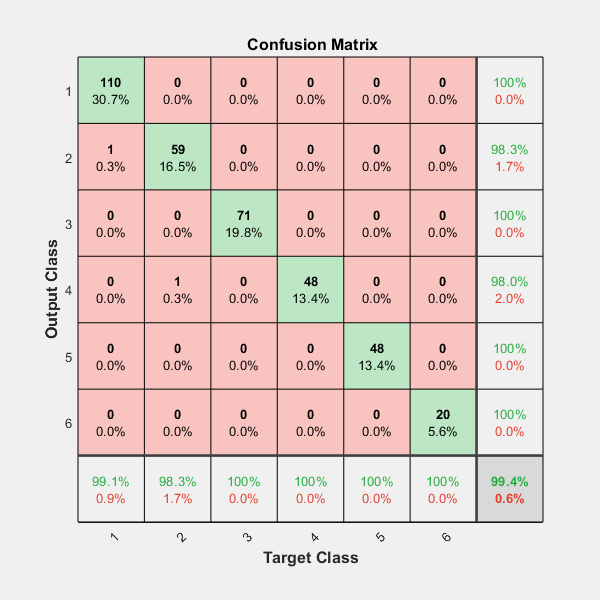


% Zobrazenie kontingencnej tabulky
figure, plotconfusion(targets,outputs)